filename = 'NonInstrumental-SPE-03-30-2020(01)';
load([filename,'_D.mat']);

Calculate reveal probability by block type over session

let's do this block by block

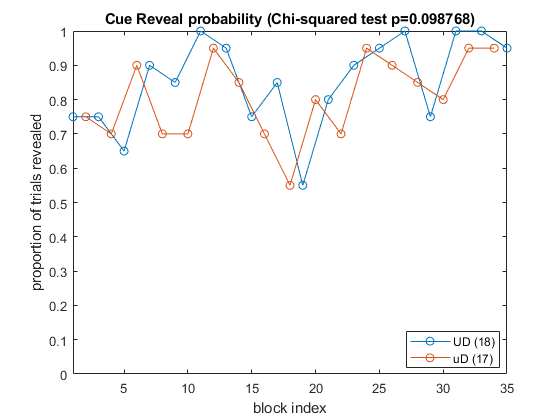

revealProb = zeros(D.BlockIndex(end),1); 
BigU = false(size(revealProb));

for blkind = 1:D.BlockIndex(end)
    BigU(blkind) = D.BlockID(find(D.BlockIndex==blkind,1))==1;
    if sum(D.BlockIndex==blkind & D.Rewarded)==0
        if blkind == D.BlockIndex(end)
            revealProb = revealProb(1:end-1);
            BigU = BigU(1:end-1);
        else
            revealProb(blkind) = NaN;
        end
    else
        revealProb(blkind) = ...
            sum(D.BlockIndex==blkind & D.CueRevealed & D.Rewarded) ...
            / sum(D.BlockIndex==blkind & D.Rewarded);
    end
end

[~,~,pne] = CompareProportions(...
    sum(D.BlockID==1 & D.CueRevealed & D.Rewarded),...
    sum(D.BlockID==1 & D.Rewarded),...
    sum(D.BlockID==2 & D.CueRevealed & D.Rewarded),...
    sum(D.BlockID==2 & D.Rewarded));
figure;
blocks =1:length(revealProb);
plot(blocks(BigU),revealProb(BigU),'-o','MarkerSize',6);
hold on;
plot(blocks(~BigU),revealProb(~BigU),'-o','MarkerSize',6);

ylim([0 1]); xlim([1,blocks(end)]);
xlabel('block index');
ylabel('proportion of trials revealed')
legend({['UD (' num2str(sum(BigU)) ')'],...
    ['uD (' num2str(sum(~BigU)) ')']},'location','best');
title(['Cue Reveal probability (Chi-squared test p=',num2str(pne),')'])
saveas(gcf,['reveal_probability',filename(find(filename=='-',1):end),'.png']);

code for chi-squared proportion test

function [p1g2,p1l2,pne] = CompareProportions(x1,n1,x2,n2)
p1 = x1/n1;
p2 = x2/n2;
p = (x1+x2)/(n1+n2);
sp = sqrt(p*(1-p)*(1/n1+1/n2));
z = (p1-p2)/sp;
p1g2 = 1 - normcdf(z); %p1>p2
p1l2 = normcdf(z); %p1<p2
pne = 2*(1 - normcdf(abs(z))); %p1=/=p2
end